L_i = 1.2e-3;        % H
L_g = 0.7e-3;        % H
C_f = 9e-6;          % F
R_d = 8;             % Ohms

T_S = 1e-6;          % s

s = tf('s');
T_D = (1/(1+T_S*s));
G_F = ((1/(L_i*s))*(((s^2)+(s*R_d/L_g)+(1/(L_g*C_f)))/((s^2)+(s*((L_i*R_d+L_g*R_d)/(L_i*L_g)))+((L_i+L_g)/(L_i*L_g*C_f)))))*T_D;

omega_0 = 2*pi*50;   % rad/sec
omega_c = 0.5;       % rad/sec
omega_c3 = 2.5;    % rad/sec
omega_c5 = 4.5;    % rad/sec
omega_c7 = 10;     % rad/sec

C = @(K) K(1) + ...
         K(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))) + ...
         K(3)*((2*omega_c3*s)/((s^2) + (2*omega_c3*s) + ((3*omega_0)^2))) + ...
         K(4)*((2*omega_c5*s)/((s^2) + (2*omega_c5*s) + ((5*omega_0)^2))) + ...
         K(5)*((2*omega_c7*s)/((s^2) + (2*omega_c7*s) + ((7*omega_0)^2)));

K = 1e3*[0.005    1.1196    0.1570    0.0470    0.0334];

% % % % % % % % % % % % % % % % % % % % % % % % % % 
%  K = BB(num,:)
K = [6.6807  453.2598   74.5026  133.7893   34.6425]

K =     6.6807  453.2598   74.5026  133.7893   34.6425


K = [6.0669  418.8029   25.3298   12.6577   45.8612]

K =     6.0669  418.8029   25.3298   12.6577   45.8612



% Closing the loop:
G_cl = feedback(G_F*C(K),1);

K_fp = [6.8  1498.72  211.208  83.867  40.834]

K_fp = 1.0e+03 *

    0.0068    1.4987    0.2112    0.0839    0.0408


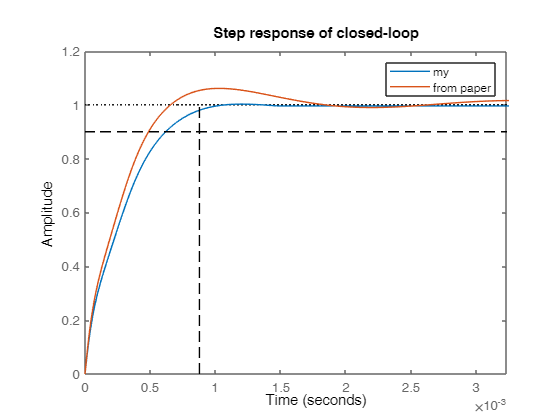


% Closing the loop:
G_cl_fp = feedback(G_F*C(K_fp),1);

% Plotting the step response of the closed-loop system:
% step(G_cl,G_cl_fp)
h2 = stepplot(G_cl,G_cl_fp); % Use this command to return plot handle to programmatically customize the plot. 
hold on
plot([stepinfo(G_cl).TransientTime stepinfo(G_cl).TransientTime],[0 1],'k--')
plot([stepinfo(G_cl_fp).TransientTime stepinfo(G_cl_fp).TransientTime],[0 1],'r--')
plot([0 1],[0.9 0.9],'k--')

p = getoptions(h2);
p.XLim = {[0, 0.00323383]};
p.YLim = {[0, 1.2]};
setoptions(h2,p);



title('Step response of closed-loop')
legend("my","from paper");

hold off

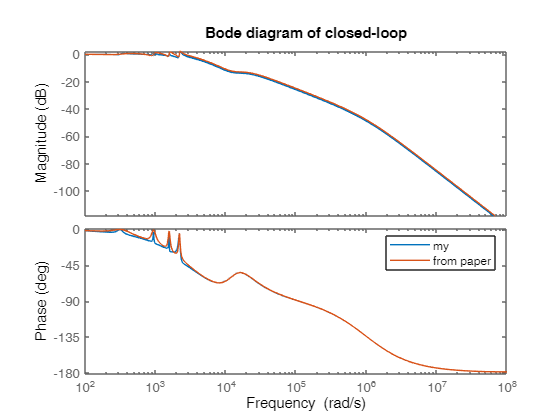

bode(G_cl,G_cl_fp);
title('Bode diagram of closed-loop')
legend("my","from paper");

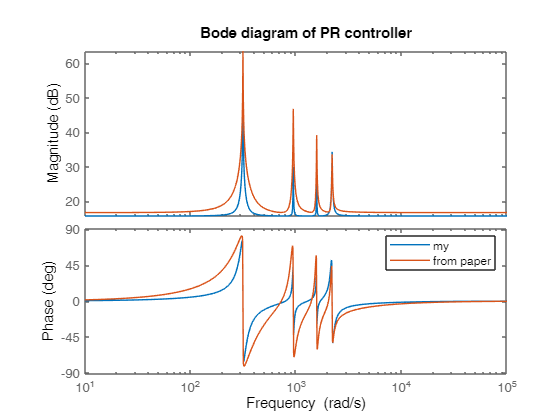


bode(C(K),C(K_fp));
title('Bode diagram of PR controller')
legend("my","from paper");

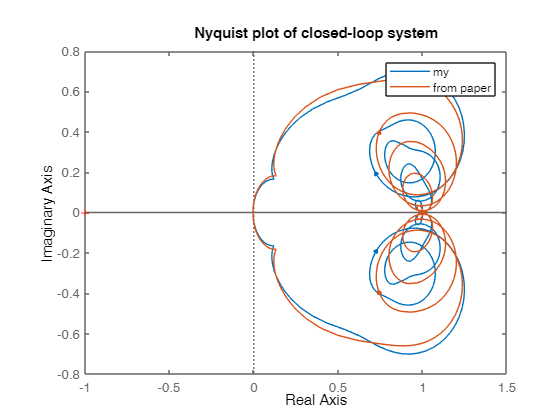


nyquist(G_cl,G_cl_fp)
title('Nyquist plot of closed-loop system')
legend("my","from paper");



% Nastavení parametrů signálu
fs = 50000*2*pi; % vzorkovací frekvence
f0 = 50*2*pi; % hlavní frekvence signálu
t = 0:(1/fs):(1/f0); % časový vektor
U = 385; % amplituda signálu
H = 30; % max harmonicka

% x = U*square(2*pi*t*f0,50); % Obdélníkový signál

% Vytvoření základního sinusového signálu
x = U*sin(2*pi*f0*t);

h = 3:2:H;
for n = h
    x = x + (U*(1/n))*sin(2*pi*n*f0*t);
end

% Vykreslení vstupního signálu
plot(t,x);

pxx_norm_vstup = 100*(periodogram(x,[],length(x),fs))/(max(periodogram(x,[],length(x),fs))); % normalizace hodnot na procenta

y = lsim(G_cl,x,t);
pxx_norm_vystup = 100*(periodogram(y,[],length(x),fs))/(max(periodogram(y,[],length(x),fs))); % normalizace hodnot na procenta

y_fp = lsim(G_cl_fp,x,t);
pxx_norm_vystup_fp = 100*(periodogram(y_fp,[],length(x),fs))/(max(periodogram(y_fp,[],length(x),fs))); % normalizace hodnot na procenta


thd = 0;
for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n-1) + ". harmonické je: %0.2f%%\n",pxx_norm_vstup(n));
    thd = thd + pxx_norm_vstup(n);
end

THD 3. harmonické je: 11.10%
THD 5. harmonické je: 3.99%
THD 7. harmonické je: 2.03%
THD 9. harmonické je: 1.23%
THD 11. harmonické je: 0.82%
THD 13. harmonické je: 0.58%
THD 15. harmonické je: 0.44%
THD 17. harmonické je: 0.34%
THD 19. harmonické je: 0.27%
THD 21. harmonické je: 0.22%
THD 23. harmonické je: 0.18%
THD 25. harmonické je: 0.15%
THD 27. harmonické je: 0.13%
THD 29. harmonické je: 0.11%



fprintf('THD je: %0.2f%%\n',thd);

THD je: 21.58%



hold on
plot(t,y);
% plot(t,y_fp);
title('Efficiency of controlled system','FontName','Courier');
xlabel('Time (s)','FontName','Courier');
ylabel('Voltage (V)','FontName','Courier');
legend("Input","Output",'FontName','Courier')

thd = 0;
for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup(n));
    thd = thd + pxx_norm_vystup(n);
end

THD 4. harmonické je: 3.21%
THD 6. harmonické je: 0.64%
THD 8. harmonické je: 0.30%
THD 10. harmonické je: 0.18%
THD 12. harmonické je: 0.11%
THD 14. harmonické je: 0.07%
THD 16. harmonické je: 0.05%
THD 18. harmonické je: 0.03%
THD 20. harmonické je: 0.02%
THD 22. harmonické je: 0.02%
THD 24. harmonické je: 0.02%
THD 26. harmonické je: 0.01%
THD 28. harmonické je: 0.01%
THD 30. harmonické je: 0.01%


fprintf('THD je: %0.2f%%\n',thd);

THD je: 4.67%



thd = 0;
for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup_fp(n));
    thd = thd + pxx_norm_vystup_fp(n);
end

THD 4. harmonické je: 3.20%
THD 6. harmonické je: 0.62%
THD 8. harmonické je: 0.29%
THD 10. harmonické je: 0.17%
THD 12. harmonické je: 0.11%
THD 14. harmonické je: 0.07%
THD 16. harmonické je: 0.05%
THD 18. harmonické je: 0.03%
THD 20. harmonické je: 0.02%
THD 22. harmonické je: 0.02%
THD 24. harmonické je: 0.01%
THD 26. harmonické je: 0.01%
THD 28. harmonické je: 0.01%
THD 30. harmonické je: 0.01%


fprintf('THD je: %0.2f%%\n',thd);

THD je: 4.61%


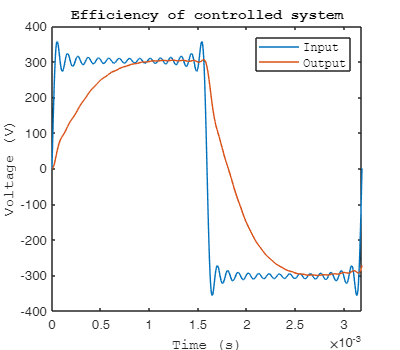


set(gcf, 'Position', [0, 0, 400, 350])
print(gcf, '-dpng', 'porovnani_THD_en.jpg')